## Cálculo dos motores do MANSUP

clear all;
close all;
clc;

Alt = 10;               % altitude de lancamento

% Calculo dos parametros atmosfericos
[Temp, VSom, P, Ro] = atmosisa(Alt);

% Coeficiente de arrasto (dome ogival) 
% [mach, CD]
VCd = ...
    [0    0.33 
     0.7  0.33
     0.9  0.42
     1.1  0.67
     1.2  0.68
     1.5  0.70
     1.8  0.70
     2.0  0.67
     2.5  0.62
     3.0  0.61
     3.5  0.61];


Vi = 0.0*VSom;          % velocidade de lancamento
Vf = 0.9*VSom;          % velocidade-alvo apos queima do booster

MTotal = 855;           % Massa total do míssil (kg)
L_Missil = 5.8;         % Comprimento total do míssil (m)
DRef = 0.35;            % Diâmetro do míssil (m)
SRef = pi*DRef^2/4;     % Diâmetro de referência (m2)

% Estimativa da Cabeça de Guerra
Dens_CDG = 3000;        % Densidade da cabeça de guerra (kg/m3)
M_CDG =  165;           % Massa da cabeça de guerra (kg)
V_CDG = M_CDG/Dens_CDG; % Volume da Cabeça de Guerra
L_CDG = V_CDG/(SRef);   % Comprimento da Cabeça de Guerra


## Booster

Geometrias possíveis para o grão propelente

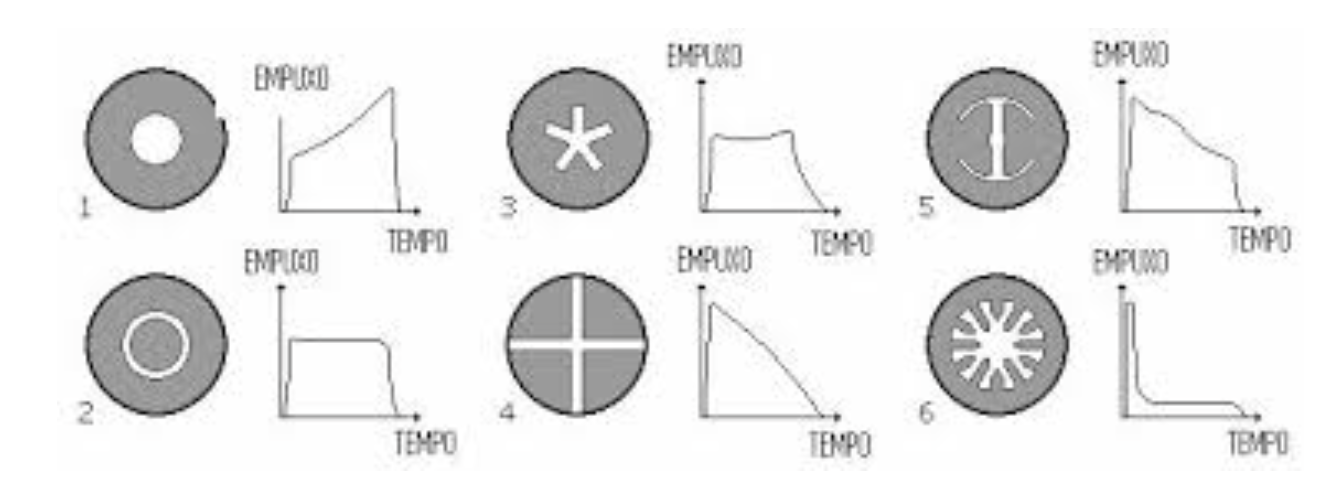

#### Geometria 3: Estrela

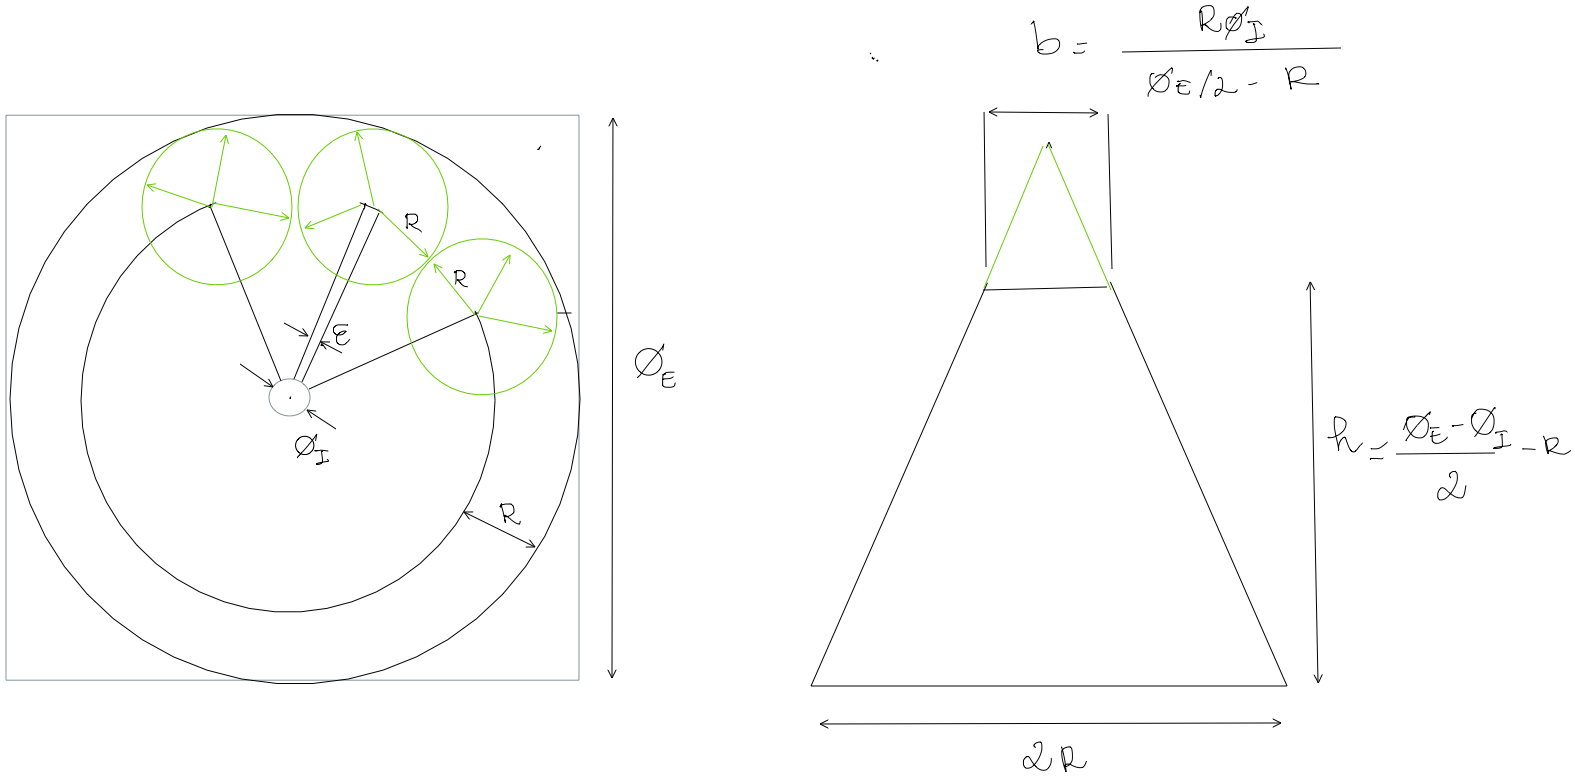

Espessura do Propelente: $R = T_{q}V_q$

Diâmetro interno: $\phi_I$

Distância entre pétalas: $\epsilon$

Base maior da pétala: $B_{star} \approx 2R$

Base menor da pétala: $b_{star} \approx \frac{R\phi_I}{\phi_E/2 - R}$

Número de pétalas: $N_{star} = INT\left( \frac{2\pi(\phi_E/2 - R)}{2R + \epsilon} \right)$

Altura da pétala: $h_{star} \approx \frac{\phi_E - \phi_I}{2} -  R$

Área da pétala: $A_{star} = \frac{(b_{star} + B_{star})}{2}h_{star}$

Volume da pétala: $V_{star} =  A_{star} L $

Volume de tarugo com comprimento L, diâmetro $\phi_E$ e espessura R: $V = \frac{\pi}{4}L[\phi_E^2 - (\phi_E - 2R)^2] =  \pi L R(\phi_E - R)$

Volume de propelente: $V_p = \pi LR (\phi_E - R) + N_{star}V_{star} =  L  \left[ \pi R (\phi_E-R)+N_{star}A_{star} \right]$


PhiEB = DRef - 0.040;   % diametro externo do booster
PhiIB = 0.06;           % diametro interno do propelente

VqB = 0.010;            % velocidade de queima do booster (8 a 9 mm/s @ 7MPa)
IspB = 220;             % impulso especifico do booster
RoB = 1700;             % densidade do propelente (1,65 a 1,75 g/cm3)

% Tempo de queima do Booster
TqB = 4;                % Ganho de velocidade/controle o mais rápido possível

% Dimensões transversais do Booster
RB = TqB*VqB;            % Espessura do booster
EpsB = 0.01;             % Separação entre as estrelas

% Calculo da forca necessaria para o booster
AcelB = (Vf - Vi)/TqB;
Fb = AcelB*MTotal;

% Calculo da massa, volume
MpB = Fb*TqB/(IspB*9.8);
VolB = MpB/RoB;

% Estrela
NStar = floor(2*pi*(PhiEB/2 - RB)/(2*RB + EpsB));   % número de petalas
EpsTB = (2*pi*(PhiEB/2 - RB) - NStar*2*RB)/NStar;   % Separação entre pétalas
hStar = (PhiEB - PhiIB)/2 - RB;                     % Altura da pétala
BStar = 2*RB;                                       % Base maior da pétala
bStar = RB*PhiIB/(PhiEB/2 - RB);                    % Base menor da pétala
AStar = (BStar + bStar)*hStar/2;                    % Área da pétala

% Comprimento do booster
LengthB = VolB/(pi*RB*(PhiEB - RB) + NStar*AStar);

% Fator de enchimento
FilFactor = MpB/(RoB*pi*PhiEB^2*LengthB/4);

% Peso do vaso do booster
RoAco = 7850;                                   % (kg/m3) densidade do aço
RVasoB = 0.005;                                 % (mm) espessura do vaso
VolVasoB = pi*LengthB*RVasoB*(DRef - RVasoB);   % Volume do vaso 
MVasoB = VolVasoB*RoAco;

MachCruz = 0.9;         % Mach de cruzeiro a baixa altura
VCruz = MachCruz*VSom;

% Calculo do arrasto no cruzeiro
Cd = interp1(VCd(:,1),VCd(:,2),MachCruz);
DragCruz = 0.5*Ro*VCruz^2*SRef*Cd;


## Sustainer

Impulso específico: $I_{sp} = \frac{FT_q}{mg} = \frac{F}{g\dot{m_p}}$

Taxa de queima do propelente: $\dot{m_p} = \rho S \frac{L_p}{T_q} = \rho S V_q$

Força do sustainer: $F = I_{sp}g\rho SV_q = F_{Drag}$

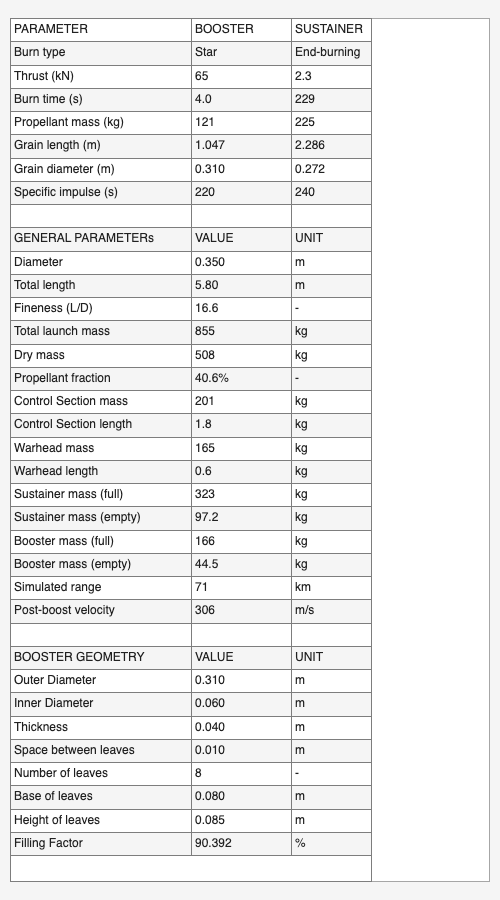


% Dimensionamento do sustainer
IspS = 240;             % Impulso especifico do sustainer
VqS = 0.010;            % Velocidade de queima do sustainer (13 a 14 mm/s @ 7 MPa)
RoS = 1700;             % Densidade do sustainer (1,65 a 1,75 g/cm3)

% Calculo do diametro do sustainer
SSust = DragCruz/(IspS*9.8*RoS*VqS);
PhiES = sqrt(4*SSust/pi);

% Calculo do tempo de queima do sustainer para alcance de 70 km
TqS = 70000/VCruz;
LengthS = TqS*VqS;
MpS = SSust*LengthS*RoS;

% Peso do vaso do sustainer
RVasoS = 0.005;                                 % (mm) espessura do vaso
VolVasoS = pi*LengthS*RVasoS*(DRef - RVasoS);   % Volume do vaso 
MVasoS = VolVasoS*RoAco;

% Comprimento do míssil
L_Tubeira = 0.10;           % Comprimento da tubeira (m)
L_Cont = L_Missil - (L_CDG + LengthB + LengthS + L_Tubeira);
M_Cont = MTotal - (MpB+MVasoB) - (MpS+MVasoS) - M_CDG;
Mf = MTotal - MpB - MpS;

% Vetor de empuxo e massa de propelente
VProp = ...
    [ 0              Fb        MpB+MpS
      TqB            Fb        MpS
      TqB+0.001      DragCruz  MpS
      TqB+TqS        DragCruz  0
      TqB+TqS+0.001  0         0];
      

sim('SimX');

% ── Figure 4: Tabular Summary ───────────────────────────────────────────
figure('Name','Design Summary','NumberTitle','off', ...
       'Position',[1020 100 500 900]);
axis off;
data = {
    'PARAMETER',                 'BOOSTER',           'SUSTAINER';
    'Burn type',                 'Star',              'End-burning';
    'Thrust (kN)',               sprintf('%.0f', Fb/1e3),  sprintf('%.1f', DragCruz/1e3);
    'Burn time (s)',             sprintf('%.1f', TqB), sprintf('%.0f', TqS);
    'Propellant mass (kg)',      sprintf('%.0f', MpB), sprintf('%.0f', MpS);
    'Grain length (m)',          sprintf('%.3f', LengthB), sprintf('%.3f', LengthS);
    'Grain diameter (m)',        sprintf('%.3f', PhiEB), sprintf('%.3f', PhiES);
    'Specific impulse (s)',      num2str(IspB),         num2str(IspS);
    '',                          '',                   '';
    'GENERAL PARAMETERs',        'VALUE',              'UNIT';
    'Diameter',                  sprintf('%.3f',DRef),  'm';
    'Total length',              sprintf('%.2f',L_Missil),'m';
    'Fineness (L/D)',            sprintf('%.1f',L_Missil/DRef),'-';
    'Total launch mass',         sprintf('%.0f',MTotal), 'kg';
    'Dry mass',                  sprintf('%.0f',Mf),    'kg';
    'Propellant fraction',       sprintf('%.1f%%',(MTotal - Mf)/MTotal*100),'-';
    'Control Section mass',      sprintf('%.0f',M_Cont),'kg';
    'Control Section length',    sprintf('%.1f',L_Cont),'kg';
    'Warhead mass',              sprintf('%.0f',M_CDG),'kg';
    'Warhead length',            sprintf('%.1f',L_CDG),'kg';
    'Sustainer mass (full)',     sprintf('%.0f',MVasoS + MpS),'kg';
    'Sustainer mass (empty)',    sprintf('%.1f',MVasoS),'kg';
    'Booster mass (full)',       sprintf('%.0f',MVasoB + MpB),'kg';
    'Booster mass (empty)',      sprintf('%.1f',MVasoB),'kg';
    'Simulated range',           sprintf('%.0f',Xm(end)/1e3),'km';
    'Post-boost velocity',       sprintf('%.0f',Vm(end)),'m/s';
    '',                          '',                   '';
    'BOOSTER GEOMETRY',         'VALUE',              'UNIT';
    'Outer Diameter',            sprintf('%.3f',PhiEB),  'm';
    'Inner Diameter',            sprintf('%.3f',PhiIB),  'm';
    'Thickness',                 sprintf('%.3f',RB),'m';
    'Space between leaves',      sprintf('%.3f',EpsTB),'m';
    'Number of leaves',          sprintf('%.0f',NStar), '-';
    'Base of leaves',            sprintf('%.3f',2*RB), 'm';
    'Height of leaves',          sprintf('%.3f',hStar), 'm';
    'Filling Factor',            sprintf('%.3f',FilFactor*100), '%';
};
t_tab = uitable(gcf,'Data', data, ...
    'Units','normalized','Position',[0.02 0.02 0.96 0.96], ...
    'FontSize', 9, 'RowName', {}, 'ColumnName', {}, ...
    'ColumnWidth', {180, 100, 80});

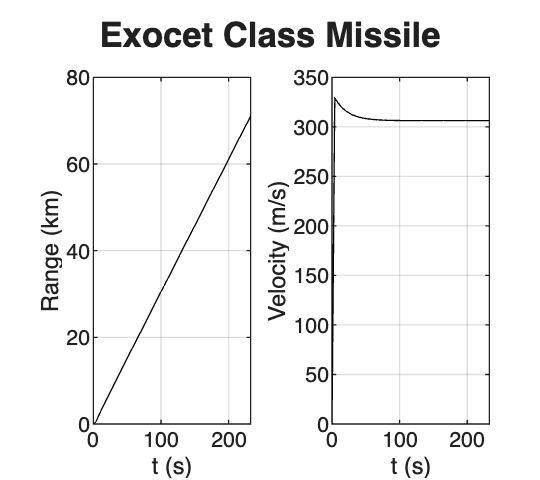



% figure
% subplot(121);
% plot(t,Xm); grid; xlabel('t (s)'); ylabel('X (m)');
% title('Distância')
% subplot(122);
% plot(t,Vm); grid; xlabel('t (s)'); ylabel('V (m/s)');
% title('Velocidade');

% ── Figure 1: Distance and Velocity vs. Time ─────────────────────────────
figure('Name','Validation — Distance and Velocity','NumberTitle','off', ...
       'Position',[100 100 900 800]);

subplot(121);
plot(t,Xm/1e3); grid; xlabel('t (s)'); ylabel('Range (km)');

subplot(122);
plot(t,Vm); grid; xlabel('t (s)'); ylabel('Velocity (m/s)');

sgtitle('Exocet Class Missile', ...
        'FontWeight','bold');